% This is the completed OFDM simulation code
% over AWGN,  no Doppler and unit channel 
% With pilot symbols
% channel gain - cosstant
% channel estimation: Zero-forcing plus linear interpoloation
% would expect a better performance than no CE

% Parameter definition
total_subchannels = 64;                        % Total number of subchannels
all_indices = 1:1:total_subchannels;           % Indices of all subcarriers (0 to K-1)
cp_length = total_subchannels / 4;             % Cyclic prefix length
modulation_order = 4;                          % Modulation order
channel_length = 1;                            % Channel length
max_iterations = 1000;                         % Number of iterations in each evaluation
SNR_vector = 0:1:15;                           % Signal-to-noise ratio vector in dB
bits_len = total_subchannels * log2(modulation_order);

% Determine the number of pilot symbols and spacing
num_pilots = min(8, total_subchannels); % Maximum 4 pilot symbols

% Generate pilot bits and symbols
pilot_bits_len = num_pilots * log2(modulation_order);
pilot_bits = randi([0 1], pilot_bits_len, 1);
pilot_symbols = qammod(pilot_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);

% Generate indices of pilot symbols
pilot_indices = zeros(num_pilots, 1);

% Ensure the last subcarrier is a pilot
pilot_indices(1) = 1;
pilot_indices(num_pilots) = total_subchannels;

% Calculate pilot spacing
pilot_spacing = (total_subchannels - 1) / (num_pilots - 1);

% Generate indices of equally spaced pilot symbols
for i = 2:num_pilots-1
    pilot_indices(i) = round((i - 1) * pilot_spacing);
end


pilot_indices

pilot_indices =      1
     9
    18
    27
    36
    45
    54
    64


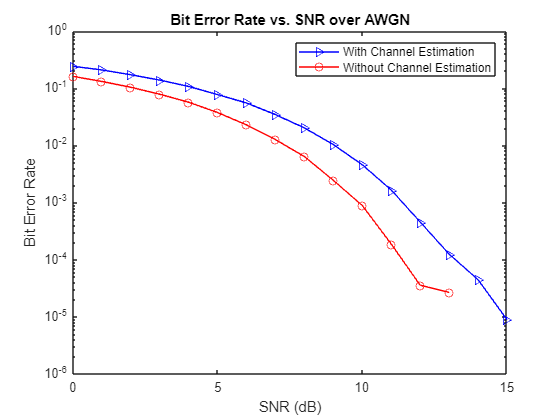


data_bits_len = bits_len - pilot_bits_len;

data_indices = setxor(1:total_subchannels, pilot_indices); % Indices of data subchannels

% Initialize array to store BER values
total_bit_error_count_array = zeros(length(SNR_vector), 1);
total_bit_error_count_array_no_ce = zeros(length(SNR_vector), 1);


for snr_index = 1:length(SNR_vector)
    SNR = SNR_vector(snr_index);
    total_bit_error_count = 0;
    total_bit_error_count_no_ce = 0; % Initialize count for each SNR

    for iteration = 1:max_iterations     
        % Generate data bits
        tx_data_bits = randi([0 1], (bits_len - num_pilots * log2(modulation_order)), 1);      

        % Modulate data bits
        tx_data_symbols = qammod(tx_data_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
        
        % Combine data symbols with pilot symbols
        tx_all_symbols = zeros(total_subchannels, 1);
        tx_all_symbols(pilot_indices) = pilot_symbols;
        tx_all_symbols(setdiff(1:total_subchannels, pilot_indices)) = tx_data_symbols;        

        % Perform IFFT
        tx_data_ifft = ifft(tx_all_symbols, total_subchannels);
        
        % Add CP
        tx_data_ifft_with_cp = [tx_data_ifft(total_subchannels - cp_length + 1 : total_subchannels); tx_data_ifft];

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Generate channel response (example: random channel taps)
        channel_response = randn(channel_length, 1) + 1i * randn(channel_length, 1);

        % Transmission through the channel
        rx_data_ifft_with_guard = filter(channel_response, 1, tx_data_ifft_with_cp);

        rx_data_ifft_with_guard = tx_data_ifft_with_cp * 20;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Adding AWGN noise 
        rx_data_ifft_with_cp_and_noise = awgn(rx_data_ifft_with_guard, SNR, 'measured');

        % Remove CP
        rx_data_ifft = rx_data_ifft_with_cp_and_noise(cp_length + 1 : total_subchannels + cp_length);
        
        % Perform FFT
        rx_all_symbols = fft(rx_data_ifft, total_subchannels);

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Calculate BER without CE
        % Extract data_symbols
        rx_data_symbols_no_ce = rx_all_symbols(data_indices);

        % Demodulation only data symbols - using nearest euclidean distance
        rx_data_bits_no_ce = qamdemod(rx_data_symbols_no_ce, modulation_order, 'OutputType', 'bit');

        % Count error bits
        bit_error_count_no_ce = sum(rx_data_bits_no_ce ~= tx_data_bits);
        total_bit_error_count_no_ce = total_bit_error_count_no_ce + bit_error_count_no_ce ;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Perform Channel estimation
        Hest = channelEstimate(rx_all_symbols, pilot_indices, pilot_symbols, all_indices);

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Perform equalisation
        rx_all_symbols = rx_all_symbols ./ Hest;

        % Extract data_symbols
        rx_data_symbols = rx_all_symbols(data_indices);

        % Demodulation only data symbols - using nearest euclidean distance
        rx_data_bits = qamdemod(rx_data_symbols, modulation_order, 'OutputType', 'bit');

        % Count error bits
        bit_error_count = sum(rx_data_bits ~= tx_data_bits);
        total_bit_error_count = total_bit_error_count + bit_error_count ;
    end

    % Calculate BER without Ce
    ber_no_ce = total_bit_error_count_no_ce / (iteration * data_bits_len);
    total_bit_error_count_array_no_ce(snr_index) = ber_no_ce;

    % Calculate BER
    ber = total_bit_error_count / (iteration * data_bits_len);
    total_bit_error_count_array(snr_index) = ber;
end


% Plotting
figure;
semilogy(SNR_vector, total_bit_error_count_array, 'b->');
hold on;
semilogy(SNR_vector, total_bit_error_count_array_no_ce, 'r-o');

xlabel('SNR (dB)');
ylabel('Bit Error Rate');
title('Bit Error Rate vs. SNR over AWGN');

legend('With Channel Estimation', 'Without Channel Estimation');

total_bit_error_count_array_no_ce

total_bit_error_count_array_no_ce =     0.1586
    0.1308
    0.1053
    0.0757
    0.0560
    0.0360
    0.0224
    0.0128
    0.0058
    0.0024


total_bit_error_count_array

total_bit_error_count_array =     0.2401
    0.2063
    0.1741
    0.1346
    0.1074
    0.0764
    0.0533
    0.0346
    0.0197
    0.0102


function Hest = channelEstimate(rx_all_symbols, pilot_indices, pilot_symbols, all_indices)
    pilot_symbols;
    % Extract the pilot values from the RX signal
    rx_pilots_symbols = rx_all_symbols(pilot_indices);
    
    % Divide by the transmitted pilot values to obtain channel estimate at pilots
    Hest_at_pilots = rx_pilots_symbols ./ pilot_symbols;
    
    % Perform interpolation between the pilot carriers to get an estimate
    % of the channel in the data carriers. Here, we interpolate absolute value and phase 
    % separately
    Hest_abs = interp1(pilot_indices, abs(Hest_at_pilots), all_indices, 'linear', 'extrap');
    Hest_phase = interp1(pilot_indices, angle(Hest_at_pilots), all_indices, 'linear', 'extrap');
    Hest = Hest_abs .* exp(1j * Hest_phase);

    % Transpose Hest to change its dimension
    Hest = Hest.';

    total_subchannels = 64;

    % Plotting
    H_exact = ones(total_subchannels, 1) * 20;
    
%     figure;
%     plot(all_indices, abs(H_exact), 'LineWidth', 2, 'DisplayName', 'Correct Channel');
%     hold on;
%     stem(pilot_indices, abs(Hest_at_pilots), 'filled', 'DisplayName', 'Pilot estimates');
%     plot(all_indices, abs(Hest), 'LineWidth', 2, 'DisplayName', 'Estimated channel via interpolation');
%     grid on;
%     xlabel('Carrier index');
%     ylabel('|H(f)|');
%     legend('FontSize', 10);
   

end